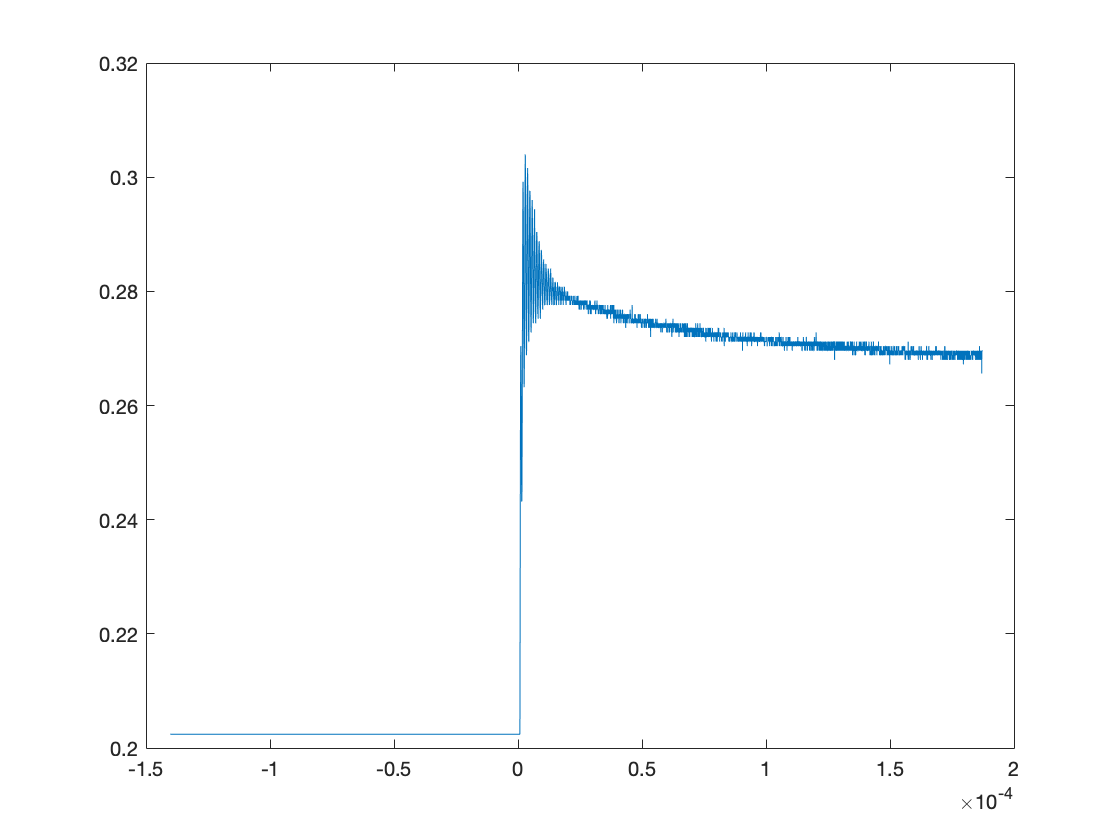

%Imported data by double clicking on it then importing it as a Column
%Vector

T = Time;
XCH = XCH1;

c = 47e-6; %Capcitor you used in F 
L = 1e-3; %Inductance in Henries 
R = .000100; %resistor used in Ohms


figure()
plot(T, XCH)

After plotting I can see that everything before the 0 is useless, so I'm going to cut off my data before then. 

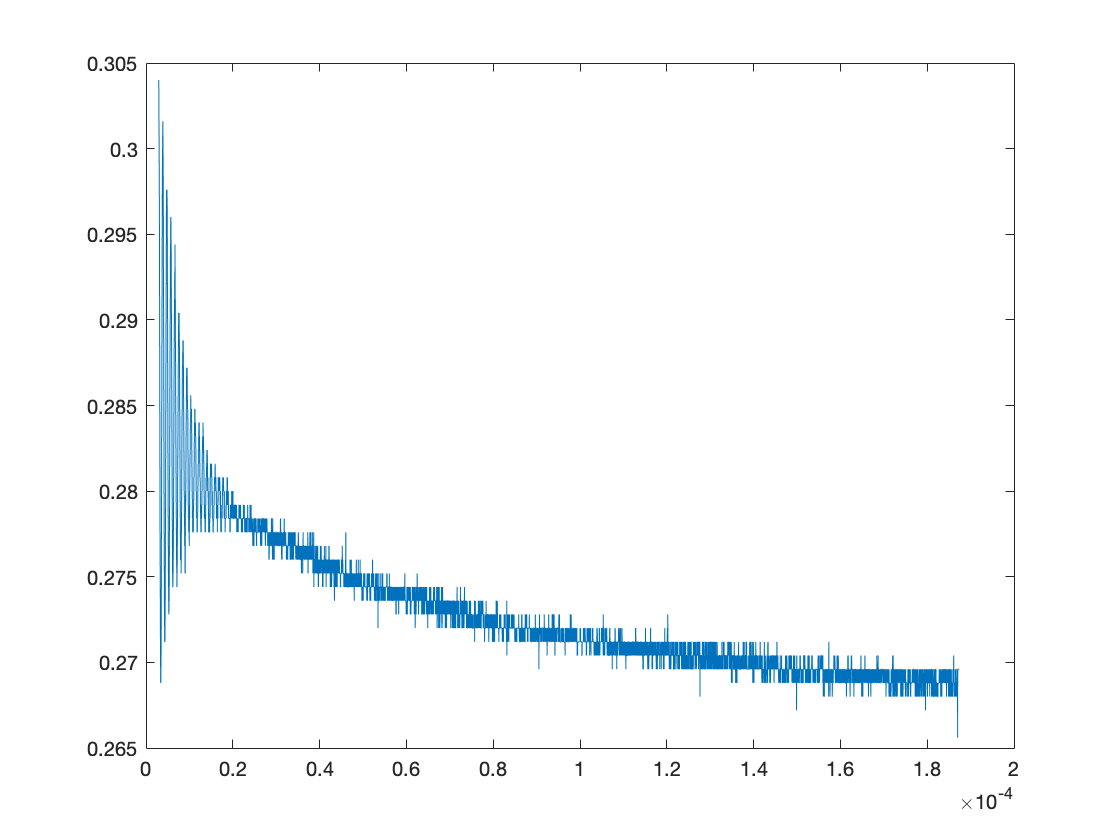

[mm,xx] = max(XCH); %This finds max for the data

figure()
plot(T(xx:end), XCH(xx:end))

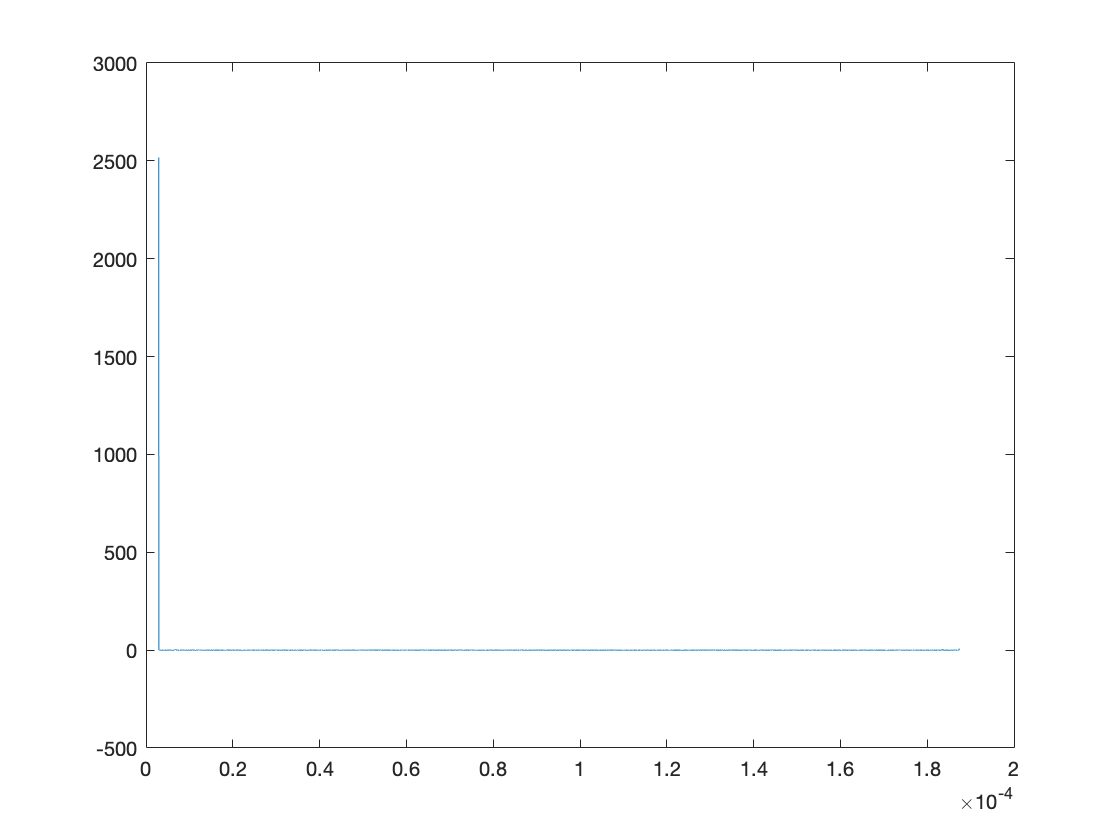


fourier = fft(XCH(xx:end));

figure()
plot(T(xx:end), fourier)


freq = max(fourier) %This is your frequency omega

freq = 2.5171e+03

Working from theory explained here [http://hyperphysics.phy-astr.gsu.edu/hbase/electric/rlcser.html](http://hyperphysics.phy-astr.gsu.edu/hbase/electric/rlcser.html)

omega = 2*pi*freq;
%Then Xc and XL can be found

Xc = 1 / omega * c; 
Xl = omega * L; 

%Impedence 
Z = sqrt(R^2 + ((Xl - Xc)^2))

Z = 15.8153


%Phase 
P = tanh((Xl - Xc )/ R)

P = 1



%Theory Omega
TheoryOmega = 1/(sqrt(L*c))

TheoryOmega = 4.6127e+03